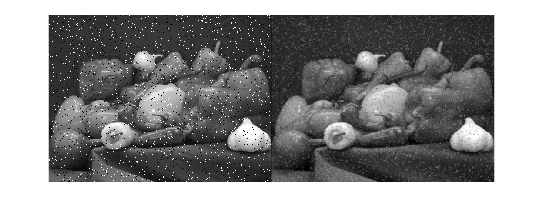

% LAB TASK 1
img = imread('peppers.png');
grayImg = rgb2gray(img);
noisyImg = imnoise(grayImg, 'salt & pepper', 0.05);
kernel = ones(3,3)/9;
[m, n] = size(noisyImg);
padded = padarray(noisyImg, [1 1]);
avgImg = zeros(m, n);
for i = 1:m
    for j = 1:n
        region = double(padded(i:i+2, j:j+2));
        avgImg(i,j) = sum(sum(region .* kernel));
    end
end
avgImg = uint8(avgImg);
figure, imshowpair(noisyImg, avgImg, 'montage');

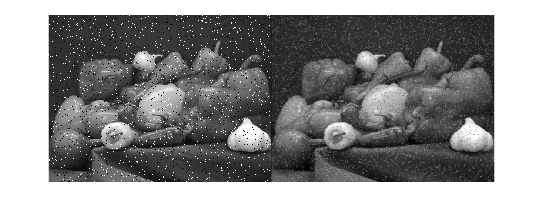


% LAB TASK 2
sigma = 1; sz = 3;
[x, y] = meshgrid(-1:1, -1:1);
gaussianKernel = exp(-(x.^2 + y.^2)/(2*sigma^2));
gaussianKernel = gaussianKernel / sum(gaussianKernel(:));
padded = padarray(noisyImg, [1 1]);
gaussImg = zeros(m, n);
for i = 1:m
    for j = 1:n
        region = double(padded(i:i+2, j:j+2));
        gaussImg(i,j) = sum(sum(region .* gaussianKernel));
    end
end
gaussImg = uint8(gaussImg);
figure, imshowpair(noisyImg, gaussImg, 'montage');

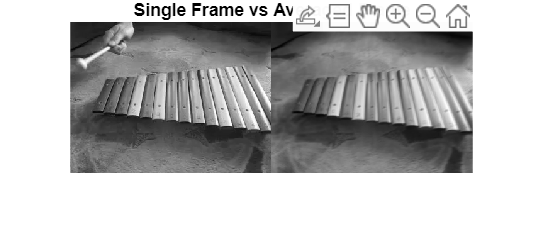


% LAB TASK 3
vid = VideoReader('xylophone.mp4');
frames = {};
while hasFrame(vid)
    frames{end+1} = rgb2gray(readFrame(vid));
end
sumFrame = double(frames{1});
for k = 2:length(frames)
    sumFrame = sumFrame + double(frames{k});
end
avgFrame = uint8(sumFrame / length(frames));
figure;
imshowpair(frames{1}, avgFrame, 'montage');
title('Single Frame vs Averaged Frame');

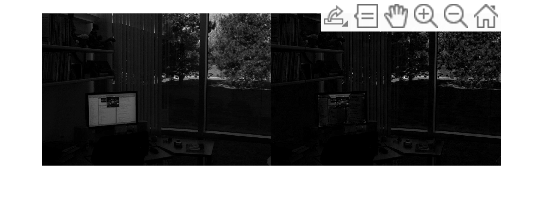



% LAB TASK 4
img = imread('office_1.jpg');
grayImg = rgb2gray(img);
background = imopen(grayImg, strel('disk',15));
subtracted = imsubtract(grayImg, background);
figure, imshowpair(grayImg, subtracted, 'montage');

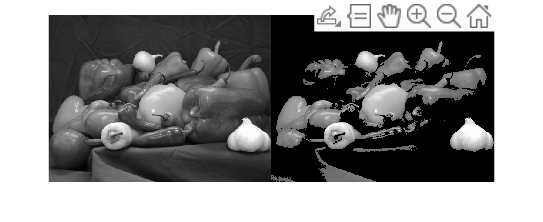


% LAB TASK 5
img = imread('peppers.png');
grayImg = rgb2gray(img);
threshold = 100;
mask = grayImg > threshold;
extracted = uint8(double(grayImg) .* mask);
notMask = ~mask;
orMask = mask | notMask;
figure, imshowpair(grayImg, extracted, 'montage');